# Tema 8

**Pb 1.** Pentru fiecare tip de spline scrieti o functie care calculeaza coeficientii spline-ului, daca se dau nodurile si valorile functiei.

**Pb 2.** Evaluati spline-ul pe o multime de puncte, daca se dau nodurile, punctele si coeficientii.

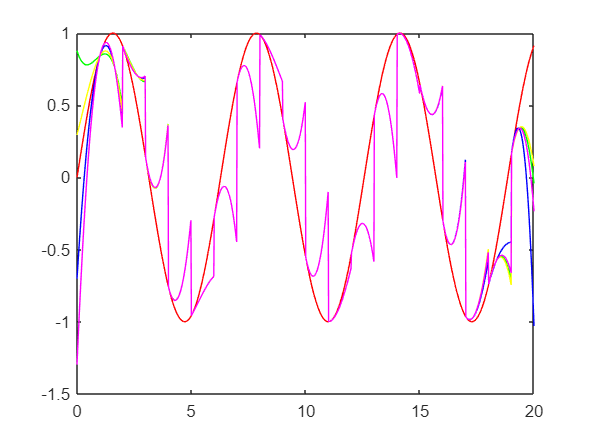

x = [1 : 20];

f = sin(x);
fderiv = cos(x);

tmp = linspace(0, 20, 1000);
plot(tmp, sin(tmp), 'r');
hold on;

% complete - albastru
[a, b, c, d] = calculateSpline(x, f, 0, fderiv);
yy = evaluateSpline(x, a, b, c, d, tmp);
plot(tmp, yy, 'b');

% match second derivates - verde
[a, b, c, d] = calculateSpline(x, f, 1, fderiv);
yy = evaluateSpline(x, a, b, c, d, tmp);
plot(tmp, yy, 'g');

% natural - galben
[a, b, c, d] = calculateSpline(x, f, 2, fderiv);
yy = evaluateSpline(x, a, b, c, d, tmp);
plot(tmp, yy, 'y');

% not a knot - magenta
[a, b, c, d] = calculateSpline(x, f, 3, fderiv);
yy = evaluateSpline(x, a, b, c, d, tmp);
plot(tmp, yy, 'm');
hold off;

**Pb 3.** Desenati o curba spline cubica parametrica ce trece printr-o multime de puncte date.

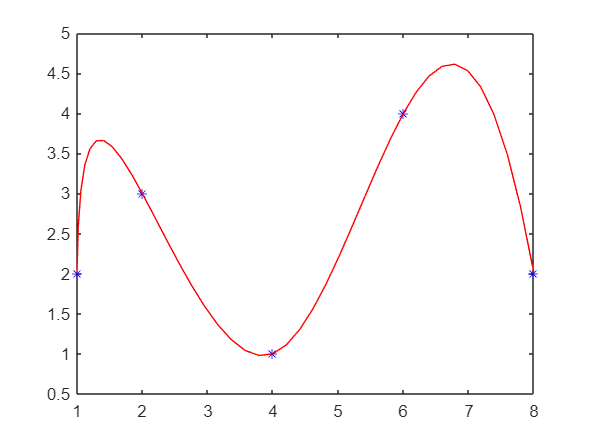

x = [1, 2, 4, 6, 8];
y = [2, 3, 1, 4, 2];

% coeficienti spline
t = 1:length(x);
ts = 1:0.1:length(x);
spline_x = spline(t, x, ts);
spline_y = spline(t, y, ts);

plot(x, y, 'b*');  % punctele
hold on;
plot(spline_x, spline_y, 'r-');  % curba spline
hold off;